% Load the model we have derived from the inversion (only for the ice shelf
% -- which means the mds model)
md = loadmodel('/Users/rishi/Desktop/ISSM/examples/Pig/Models/Ross_Inversion_Bedmachine.mat');

%Apply basal mass balance conditions
paolo ='/Users/rishi/Desktop/ISSM/examples/Data/Paolo_Ice_thickness_1996_2017.nc';

% read the parameters from the paolo datasets
x = double(ncread(paolo,'x')); 
y = double(ncread(paolo,'y'));
bmb = ncread(paolo,'melt'); % basal mass balance
smb = ncread(paolo,'smb'); % surface mass balance

% convert the data into a yearly data for the convenience
smb_yearly = squeeze(mean(reshape(smb,length(x),length(y),4,26),3));
bmb_yearly = squeeze(mean(reshape(bmb,length(x),length(y),4,26),3));

% mean of the mass balance from Paolo
smb_mean   = ncread(paolo,'smb_mean')'; % mean surface mass balance
bmb_mean = double(ncread(paolo,'melt_mean')); % mean basal melt rate

% transpose the basal mass balance and surface mass balance matrices
bmb = permute(bmb, [2 1 3]);
smb = permute(smb, [2 1 3]);

% flip the y and the data matrices to read in ISSM
y = flipud(y);
bmb = flip(bmb, 1);
smb = flip(smb, 1);

% read the time parameters
TIME = ncread(paolo,'time');
converted_time = datetime(1950, 1, 1) + days(TIME); % Convert to datetime
years = year(converted_time);

% change the nan values to zero for the sake of model run
md.basalforcings.floatingice_melting_rate (isnan(md.basalforcings.floatingice_melting_rate)) = 0;
md.smb.mass_balance (isnan(md.smb.mass_balance)) = 0;

md.basalforcings.floatingice_melting_rate = zeros(md.mesh.numberofvertices + 1, numel(TIME));
md.basalforcings.floatingice_melting_rate(end, :) = TIME;

md.smb.mass_balance = zeros(md.mesh.numberofvertices + 1, numel(TIME));
md.smb.mass_balance(end, :) = TIME;

% Loop over time steps
for i = 1:numel(TIME)
    md.basalforcings.floatingice_melting_rate (1:end-1, i) = ...
        InterpFromGridToMesh(x, y, bmb(:,:,i), md.mesh.x, md.mesh.y, 0);

    md.smb.mass_balance (1:end-1, i) = ...
        InterpFromGridToMesh(x, y, smb(:,:,i), md.mesh.x, md.mesh.y, 0);
end

% set the grounded ice melting rate
md.basalforcings.groundedice_melting_rate = zeros(md.mesh.numberofvertices,1);

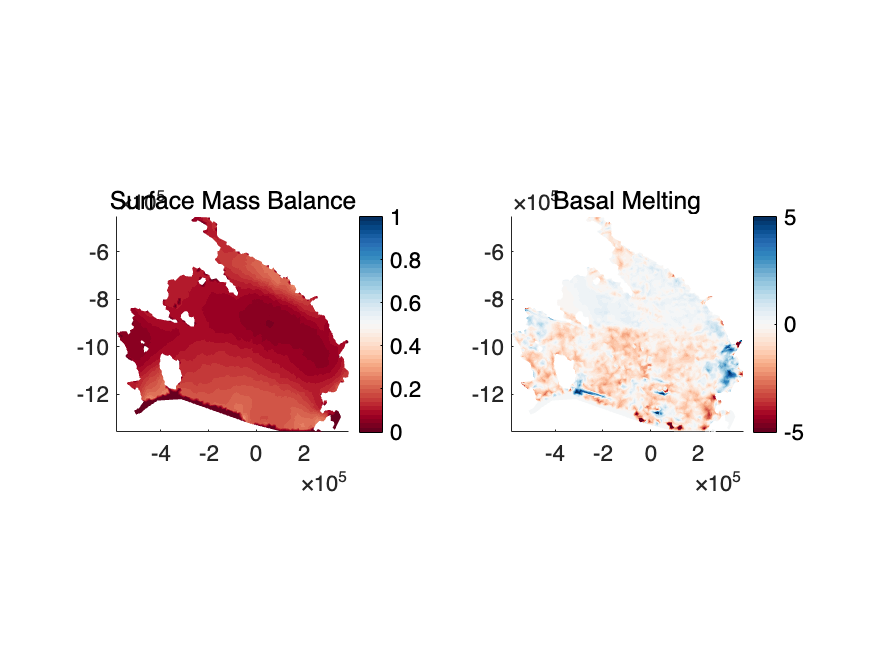


%% check whether the surface mass baalance is properly implemented
plotmodel(md,'data',md.smb.mass_balance(1:end-1, 20),'title','Surface Mass Balance','caxis#1',([0 1]),...
    'data',md.basalforcings.floatingice_melting_rate(1:end-1, 20),'title','Basal Melting','caxis#2',([-5 5]))

colormap(brewermap(50,'RdBu'))

%Indicate the components of transient to activate
md.transient.ismasstransport = 1;
md.transient.isstressbalance = 1;
md.transient.isgroundingline = 1;
md.transient.ismovingfront = 0;
md.transient.isthermal = 0;

%Specify time steps and length of simulation (years)
md.timestepping.start_time = 0;
md.timestepping.time_step = 0.1;
md.timestepping.final_time = 20;

%Disable inverse method
md.inversion.iscontrol=0;

%Initialize fields for transient and add boundary conditions
md.initialization.vx = md.results.StressbalanceSolution.Vx;
md.initialization.vy = md.results.StressbalanceSolution.Vy;
md.initialization.vel = md.results.StressbalanceSolution.Vel;
md.masstransport.spcthickness = NaN*ones(md.mesh.numberofvertices,1);

%Request additional outputs
md.transient.requested_outputs={'default','IceVolume',...
    'IceVolumeAboveFloatation','TotalSmb','TotalFloatingBmb',...
    'AverageButtressing'};

%Solve transient solution and change messages provided
md.cluster = generic('name',oshostname,'np',4);
md.verbose = verbose('solution',false);

md=solve(md,'Transient');

uploading input file and queuing script
launching solution sequence on remote cluster

Ice-sheet and Sea-level System Model (ISSM) version  4.24
(website: http://issm.jpl.nasa.gov forum: https://issm.ess.uci.edu/forum/)

call computational core:
write lock file:

   FemModel initialization elapsed time:   0.024526
   Total Core solution elapsed time:       32.4063
   Linear solver elapsed time:             27.9244 (86%)

   Total elapsed time: 0 hrs 0 min 32 sec


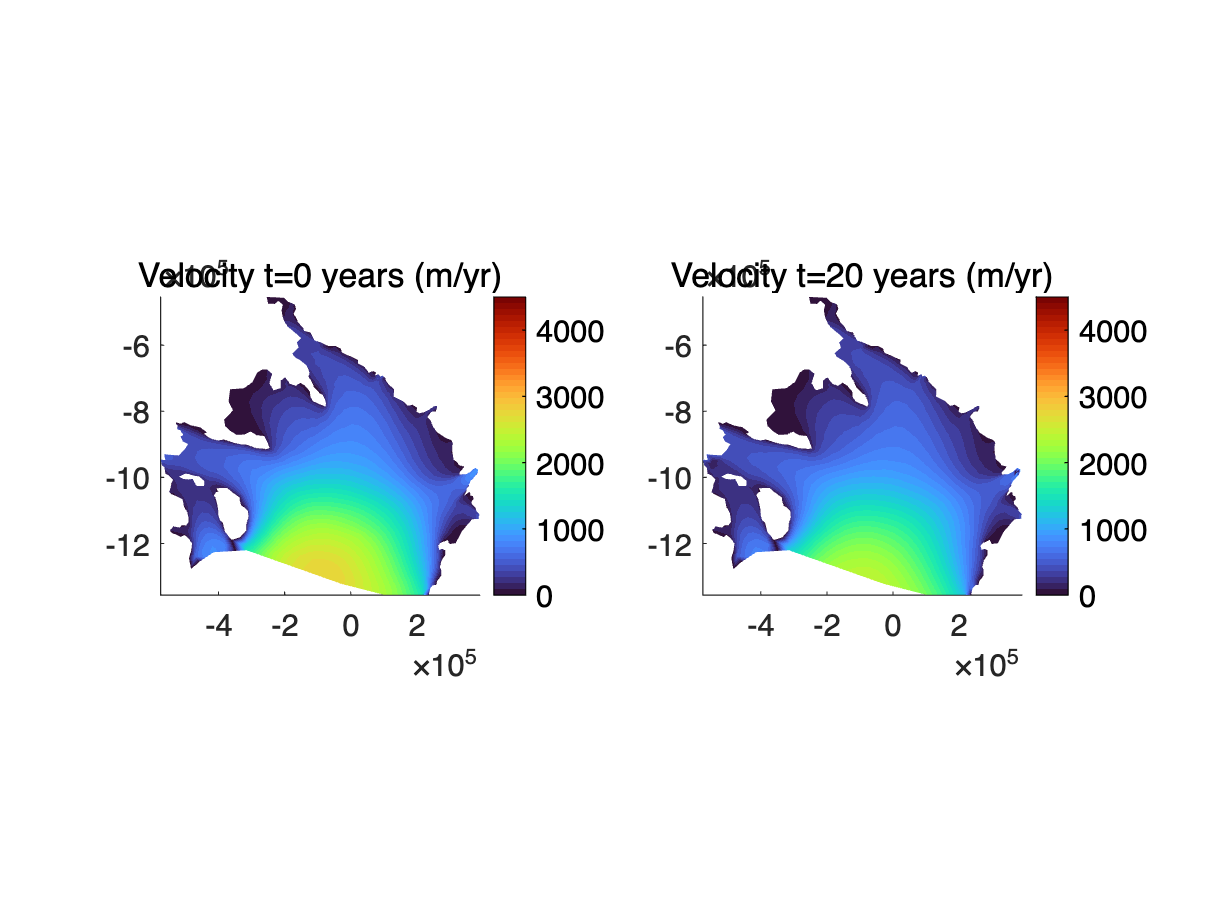

%Plot results
plotmodel(md, 'data', md.results.TransientSolution(1).Vel,'title#1', 'Velocity t=0 years (m/yr)',...
  'data', md.results.TransientSolution(end).Vel,'title#2', 'Velocity t=20 years (m/yr)',...
  'caxis#1',([0 4500]),'caxis#2',([0 4500]));

% try to produce the mechanical properties of an ice shelf from the
% transient run

% This is the stress and strain output of the first year before run
vx1 = md.results.TransientSolution(1).Vx;
vy1 = md.results.TransientSolution(1).Vy;
md = mechanicalproperties(md, vx1, vy1);
md.results.deviatoricstress_start = md.results.deviatoricstress;

% This is the stress and strain output of the end year after run
vxt = md.results.TransientSolution(end).Vx;
vyt = md.results.TransientSolution(end).Vy;
md = mechanicalproperties(md, vxt, vyt);
md.results.deviatoricstress_end = md.results.deviatoricstress;

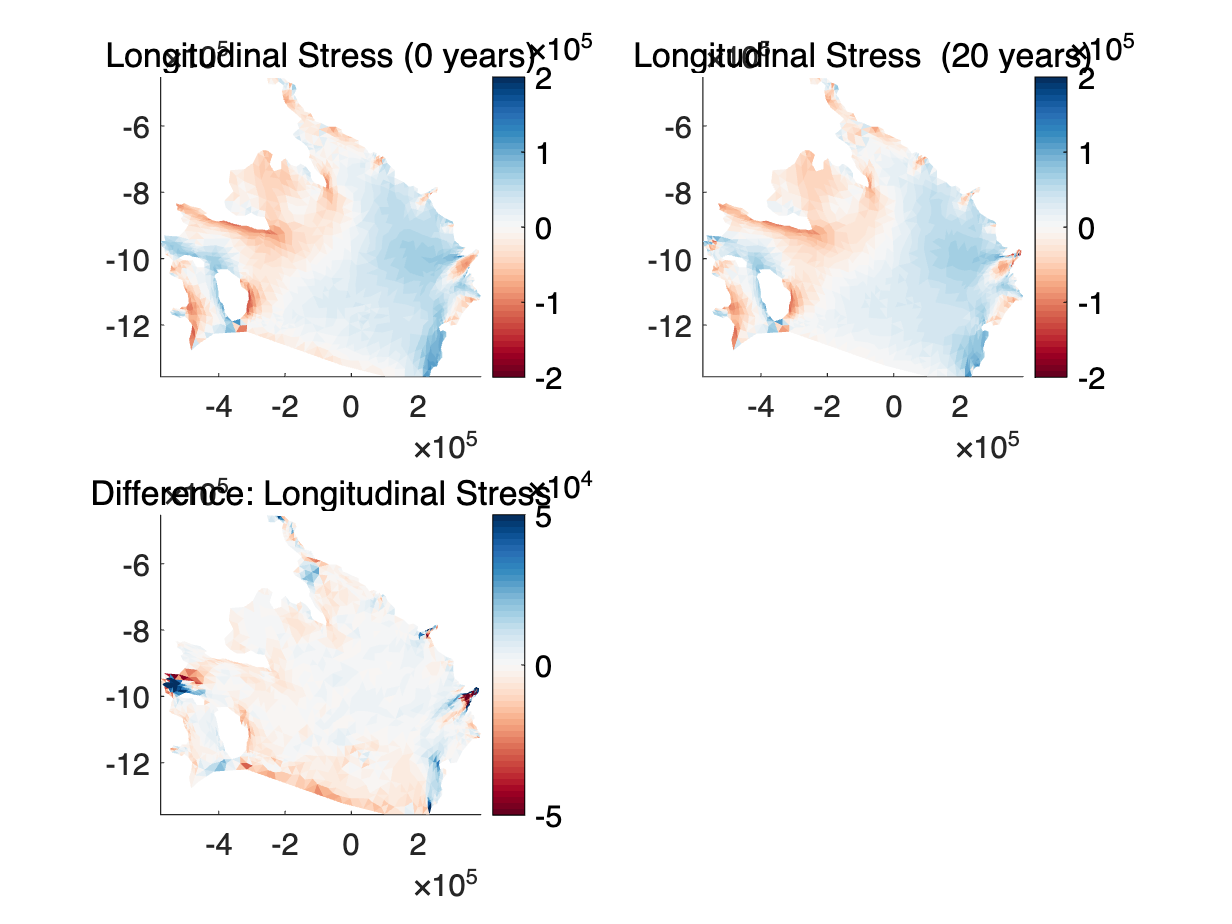

% plotting the Deviatoric Stresses for the last year
plotmodel(md,'data',md.results.deviatoricstress_start.xy,'title','Longitudinal Stress (0 years)','caxis#1',[-2e5 2e5],...
'data',md.results.deviatoricstress_end.xy,'title','Longitudinal Stress  (20 years)','caxis#2',[-2e5 2e5],...
'data',md.results.deviatoricstress_start.xy - md.results.deviatoricstress_end.xy,'title','Difference: Longitudinal Stress',...
'caxis#3',[-5e4 5e4]);

colormap(brewermap(50, 'RdBu'));

% buttressing and backstress for the initial time
for i = 1:size(md.results.TransientSolution,2)
    
    % load the velocity datasets
    vx = md.results.TransientSolution(i).Vx;
    vy = md.results.TransientSolution(i).Vy;
    [Kn_i, Backstress_Furst_i] = ...
        Furst_buttressing(md, vx, vy, false);

    Kn(:,i) = Kn_i; % Calculate Buttressing ratio for all time
    Backstress_Furst(:,i) = Backstress_Furst_i; % Backstress
end


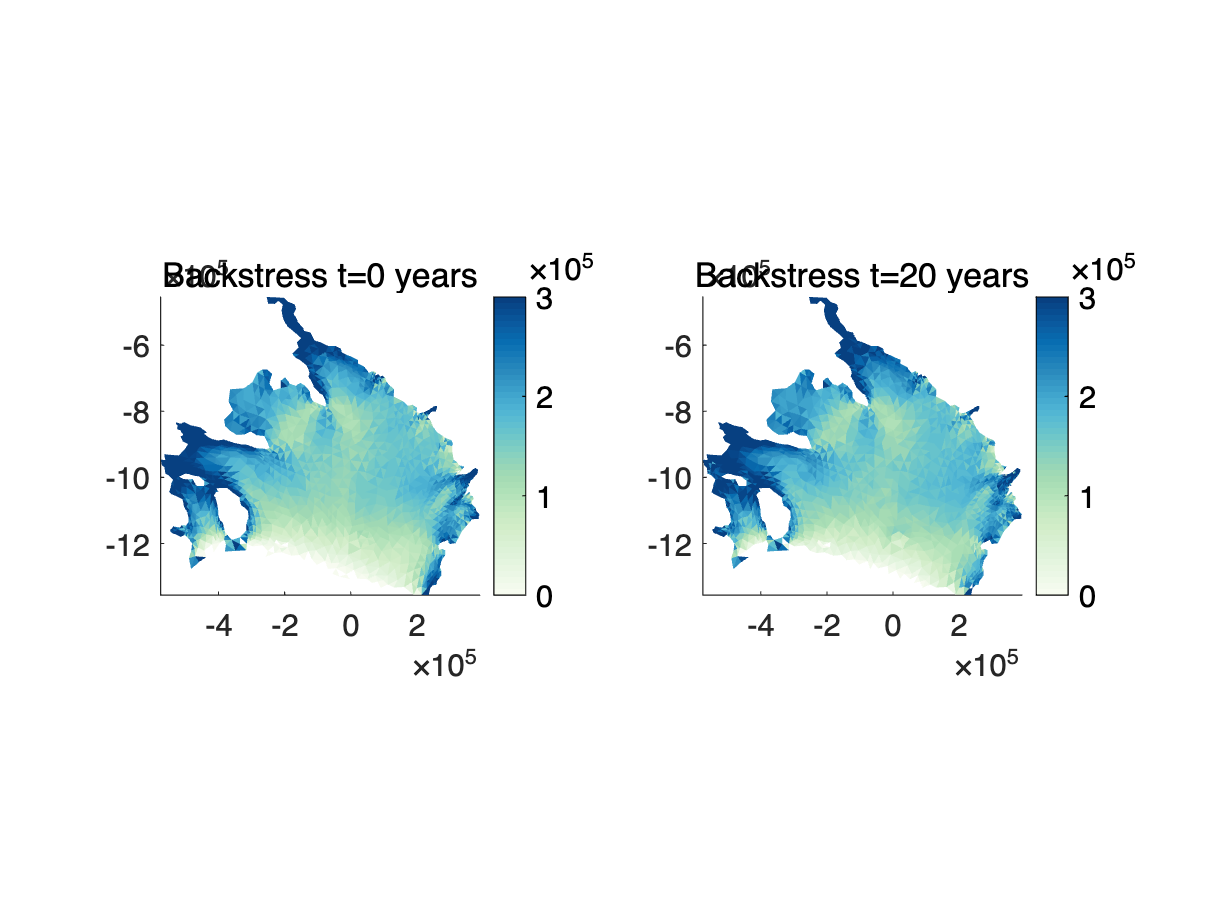

% Plot them and show the difference between them
plotmodel(md,'data',Backstress_Furst(:,1),'title', 'Backstress t=0 years','caxis#1',[0 3e5], ...
              'data',Backstress_Furst(:,end),'title', 'Backstress t=20 years','caxis#2',[0 3e5]),...

colormap(brewermap(50,'GnBu'))

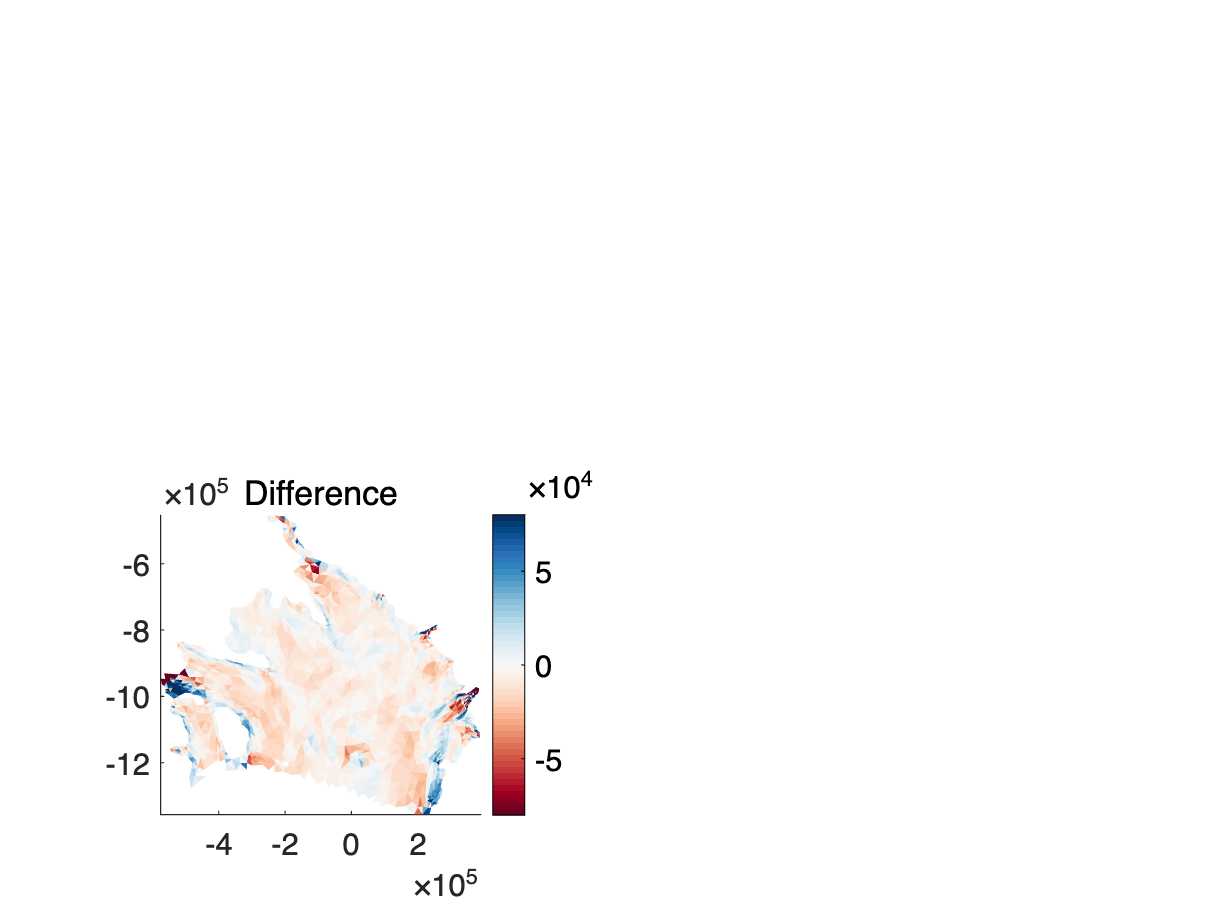

plotmodel(md,'data',(Backstress_Furst(:,1) - Backstress_Furst(:,end)),'title','Difference','caxis#1', [-8e4 8e4]);
colormap(brewermap(50,'RdBu'))